# Data

clear all; clc; 
format long g;
sensor_data= readmatrix('fort600.xlsx');
nfreemat = readmatrix('nfree-train.xlsx');
nfreemat = dlarray(nfreemat);
sensordata = dlarray(sensor_data);
inputarray = sensordata(:,:);
weight = 2*rand(8,24)-1; % normalised weights

## Normalizing Data

inputarray_n = zeros(size(inputarray)); % this will contains the normalised input array
mini = zeros(1,32);
for j=1:32
    rd = inputarray(:,j);
    mini(j) = min(rd);
    maxi(j) = max(rd);
    inputarray_n(:,j) = (inputarray(:,j) - mini(j))/(maxi(j) - mini(j));
end
training_mat = []; %

## Training ( 1 to 1600)

for i=1:1600
    input = inputarray_n(i,1:24); % we are training on normalised data
    ref_output = inputarray_n(i,25:32)';
    
%     for epoch = 1:5
        [weight, training_mat] = SGD(weight, input , ref_output,training_mat);
%     end
% save('trained_NN.mat')
end

## Output on Seen Data


   input_o = inputarray_n(1,1:24);
   output_td = []; % contains Output pred, on training data 1600*32
   for i =1: 1600
       output_o = weight*input_o';
       output_o = sigmoid(output_o);
       row = [input_o, output_o'];
       output_td = [output_td;row];
       input_o = shift(input_o,output_o'); %adding output from end and removing oldest state data from input
   end
        

## Output on unseen data

% for the initilisation data is feeded for i=1:3
s = 1601;  % start point of prediction
e = 1650; % end point of prediction 
in = inputarray_n(s,1:24);
Outputmat_n = [];%normalised input matrix
for i=1:(e-s+1)
    output = weight*in';
    output = sigmoid(output);
    row = [in, output'];
    Outputmat_n = [Outputmat_n;row];
    in = shift(in,output'); %adding output from end and removing oldest state data from input
end

% inputmat = in;
% j=3; %for updating inputmat
% for i=s:e   
%     in
% 
%     last_row = shift();
%     inputmat = [inputmat;last_row];
%     in = inputmat(j-2:j,:);
%     j = j+1;
%     input_new = ;
%     output = weight*input_rs';
%     output = sigmoid(output);
% % save('trained_NN.mat')
% end

## Denormalising output

% OUTPUT_Mat 1600*32
Outputmat = zeros(size(Outputmat_n));
for j=1:32
    Outputmat(:,j) = Outputmat_n(:,j)*(maxi(j) - mini(j))+mini(j);
end
% Prediction on training Data
output_td_dn = zeros(size(output_td));
for j =1:32
    output_td_dn(:,j) = output_td(:,j)*(maxi(j) - mini(j))+mini(j);
end

% % Training_Mat 1600*8
% training_mat_dn = zeros(size(training_mat));
% for j=1:8
%     training_mat_dn(:,j) = training_mat(:,j)*(maxi(j) - mini(j))+mini(j);
% end

## Fig for training prediction

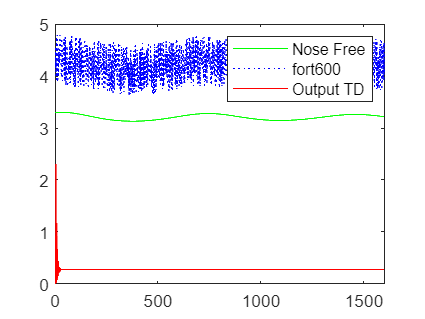

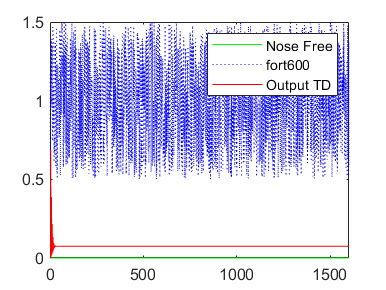

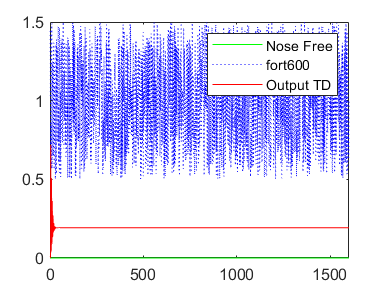

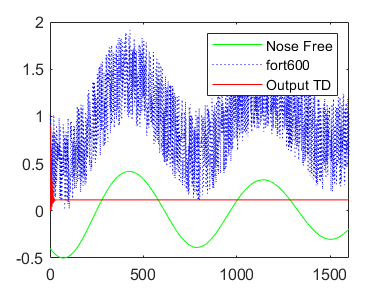

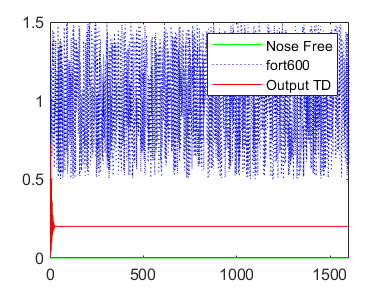

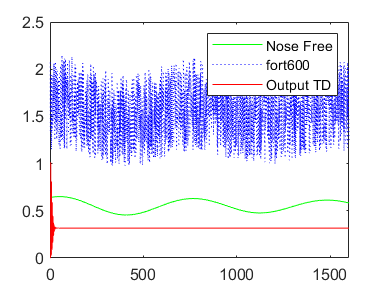

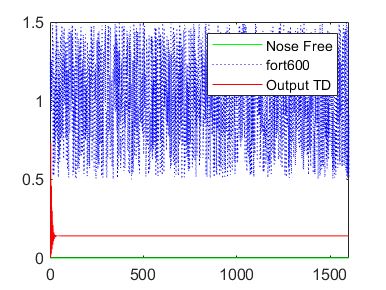

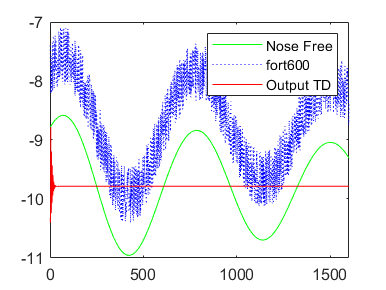

s = 1;
e = 1600;
%% fig 1 to 8 for noise free data and fort600 data
for i=25:32
    figure(i-24);
    plot(nfreemat(s:e,i),'g');
    hold on;
    plot(inputarray(s:e,i),'b:');
    plot(output_td_dn(s:e,i),'r')
    legend('Nose Free', 'fort600','Output TD');
    hold off;

end


%% fig 1 to 8 for

## Fig for Output prediction

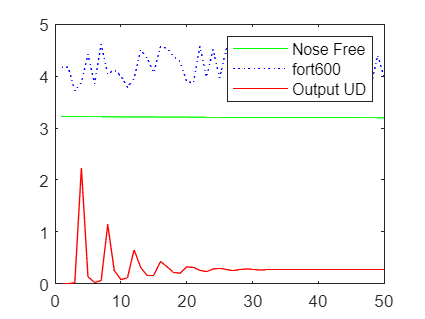

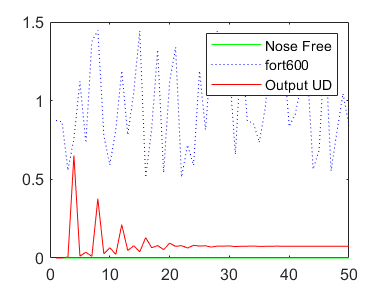

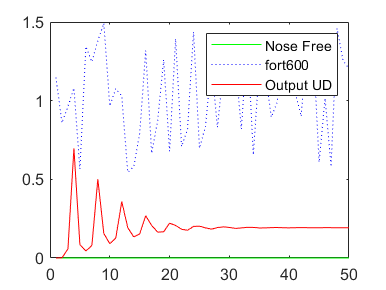

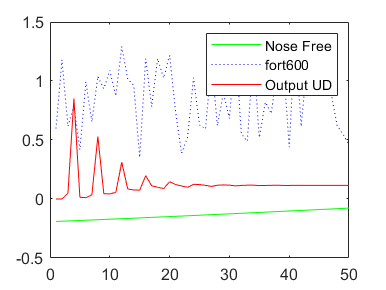

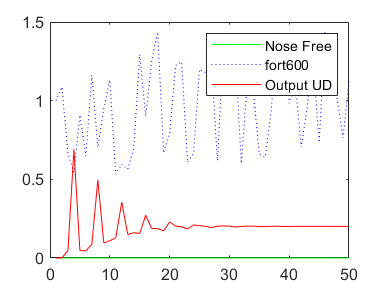

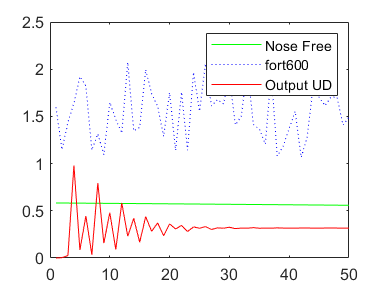

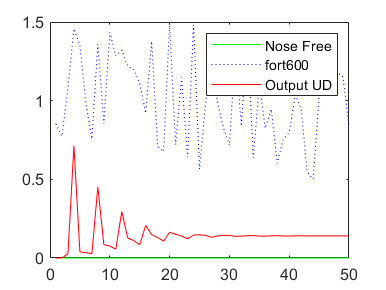

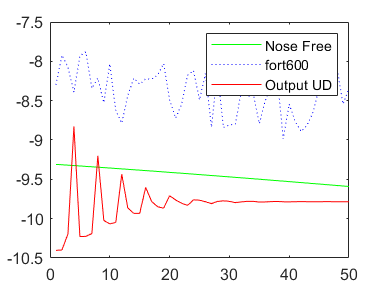

st = 1601;
ed = 1650;
for i=25:32
    figure(i);
    plot(nfreemat(st:ed,i),'g');
    hold on;
    plot(inputarray(st:ed,i),'b:');
    plot(Outputmat(1:(ed-st+1),i),'r');
    legend('Nose Free', 'fort600','Output UD');
    hold off;

end

function [weight, training_mat] = SGD(weight, input, ref_output,training_mat)
    alpha = 0.9;
    d = ref_output;
    input_tp = input';
    weighted_sum = dlarray(weight*input_tp);
    output = sigmoid(weighted_sum);
    training_mat = [training_mat; output'];
    error = d - output;
    delta = output*((ones(8,1)-output)')*error;
    dweight = alpha*(delta*input_tp');
    weight = weight - dweight;

end

function input = shift(input,output) % input is 1x24
    temp = input;
    input(1,1:16) = temp(1,9:24);
    input(1,17:24)= output;
end